# Lab2

## Objectives

### Model identification

- Parameter estimation

- Calibration & validation

Empirical model for reservoir inflows

- Linear AR model

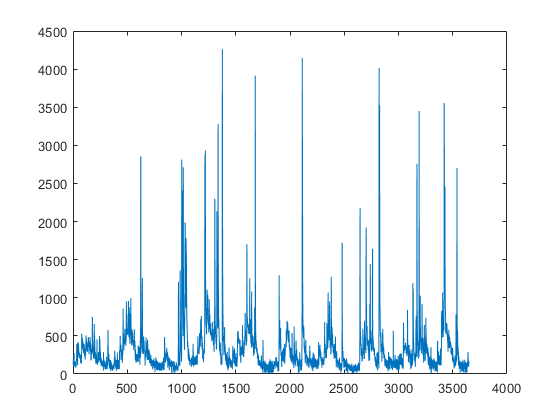

% Exercise 1 - Stationary statistics
data = load("data\Verbano_inflows_74_83_nb.txt");
% plot(data(:,2),data(:,1), '*')
plot(data)

N = size(data)

N =         3650           1


m = min(data)

m = 1.5000

M = max(data)

M = 4.2614e+03

r = range(data)

r = 4.2599e+03

x_mean = mean(data)

x_mean = 321.3367

x_var = var(data)

x_var = 1.2365e+05

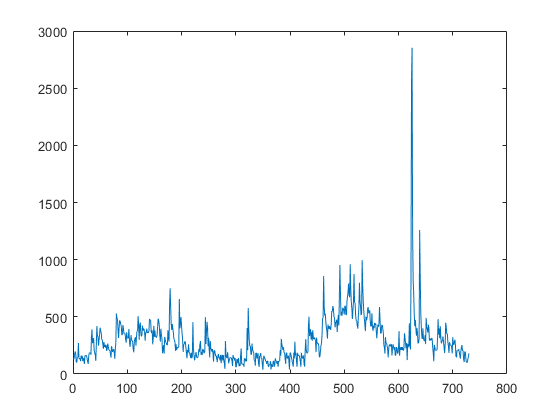

% Exercise 2 - Cyclostationary statistics
two_years = data(1:365*2);
% two_years = data;
plot(two_years)

size(two_years)

ans =    730     1


for i=1 : size(two_years)/365
    fprintf('Year %d \n',i);
    start_day = (i-1)*365 + 1;
    end_day = i*365;
    m = mean(two_years(start_day:end_day))
    v = var(two_years(start_day:end_day))
end

Year 1 


m = 242.3238

v = 1.4476e+04

Year 2 


m = 350.3627

v = 6.7712e+04


% Exercise 3 - Cyclostationary moving variance


% Exercise 4 - Param identification, linear model


% Homework - Approximate power law model


% Exercise 5 - AR(1) estimation